# 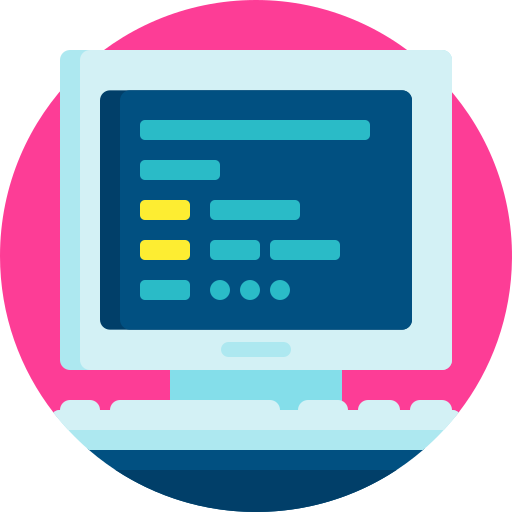

# Virtual Lab 3 - Exponential coordinates and angular velocity

#### This Virtual Lab covers Section 3.4-3.6 of the course notes

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive/USB. 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (or CMD+ENTER).

## Exponential coordinates

### Definition

Related to quaternions, **exponential coordinates** parameterise an orientation in terms of a rotation axis, represented by a unit vector $\hat{\bf v}$, and an angle of rotation $\alpha$; the vector $\alpha\hat{\bf v}\in \mathbb{R}^3$ then serves as the three-parameter exponential coordinate representation of the rotation. Writing $\hat{\bf v}$ and $\alpha$ individually is known as the **axis-angle** representation of a rotation.

Exponential coordinates can be used to describe orientation and can also be encoded in rotation matrices or quaternions to map vectors between frames. However, before we can show this result, we need to introduce the skew-symmetric matrix.

#### **Definition:** Skew-symmetric matrix

A **skew-symmetric matrix** is a square matrix whose transpose equals its negative: ${\mathbf S}^T=-{\mathbf S}$.

By this definition, the diagonal elements of  ${\mathbf S}$ must all equal zero in order to satisfy  ${\mathbf S}^T=-{\mathbf S}$ . Skew-symmetric matrices are useful in reposing a vector cross product operation as a matrix-vector multiplication, as we will show in a latter section. Given an arbitrary vector  ${\bf v}=[v_x ~v_y~v_z]^T$ , the corresponding skew-symmetric matrix is


$$\begin{array}{cc}\lfloor {\bf v} \rfloor = \left[\begin{array}{cccccccc}    0 & -v_z & v_y \\    v_z & 0 & -v_x \\    -v_y & v_x & 0    \\ \end{array}\right],\end{array}$$


which shows the symmetry across the diagonal, albeit with a sign change. Note the use of $\lfloor \dots \rfloor$ to indicate the skew-symmetric mapping.

As we will explore later in detail, if we wanted to evaluate a cross product operation such as  ${\bf v} \times {\mathbf p}$ , we could repose it as  ${\bf v} \times {\mathbf p}=\lfloor {\bf v} \rfloor{\mathbf p}$ , which is a vector multiplying into a matrix (not a cross product of two vectors). However, the result would remain the same. 

**  Question 1: **Prove that ${\bf v} \times {\mathbf p}=\lfloor {\bf v} \rfloor{\mathbf p}$ for $\{{\bf v},{\bf p}\}\in \mathbb{R}^3$. Your submission must be handwritten or typeset (using MS Word equations or LaTeX).

%Answer block (if required)


### Exponential coordinates of rotations

It can be shown that a rotation matrix, parameterised using exponential coordinates, is given by the matrix exponential mapping


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf v} \rfloor\alpha}.$$


Note that the matrix exponential differs from the standard single-element matrix exponential and in general is described by


$$\mathrm{\bf e}^{{\bf A}t}=I+t{\bf A}+\frac{t^2}{2!}{\bf A}^2+\frac{t^3}{3!}{\bf A}^3+\dots ,$$


where ${\bf A}\in \mathbb{R}^{n\times n$ is constant. For the special case when $\bf A$ is skew-symmetric, for example, ${\bf A}={\lfloor \hat{\bf v} \rfloor\alpha}$, the equation above can be reduced without loss of generality as


$${\bf R}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf v} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf v} \rfloor^2.$$


The equation above is known as **Rodrigues' formula **for rotations and is a convenient means of building a rotation matrix from exponential coordinates without having to evaluate the matrix exponential (an operation that can be computationally expensive on embedded hardware).

Writing out the above equation explicitly yields


$${\bf R}= \left[\begin{array}{cccccccc}    \mathrm{c}_\alpha+\hat{v}_x^2(1-\mathrm{c_\alpha}) & \hat{v}_x\hat{v}_y(1-\mathrm{c}_\alpha)-\hat{v}_z\mathrm{s}_\alpha & \hat{v}_x\hat{v}_z(1-\mathrm{c}_\alpha)+\hat{v}_y\mathrm{s}_\alpha \\    \hat{v}_x\hat{v}_y(1-\mathrm{c}_\alpha)+\hat{v}_z\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_y^2(1-\mathrm{c_\alpha}) & \hat{v}_y\hat{v}_z(1-\mathrm{c}_\alpha)-\hat{v}_x\mathrm{s}_\alpha  \\    \hat{v}_x\hat{v}_z(1-\mathrm{c}_\alpha)-\hat{v}_y\mathrm{s}_\alpha & \hat{v}_y\hat{v}_z(1-\mathrm{c}_\alpha)+\hat{v}_x\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_z^2(1-\mathrm{c_\alpha})    \\ \end{array}\right],$$


where $\hat{\bf v}=[\hat{v}_x~\hat{v}_y~\hat{v}_z]^T$, using the shorthand notation of $\mathrm{s}_\alpha=\sin{\alpha}$ and $\mathrm{c}_\alpha=\cos{\alpha}$.

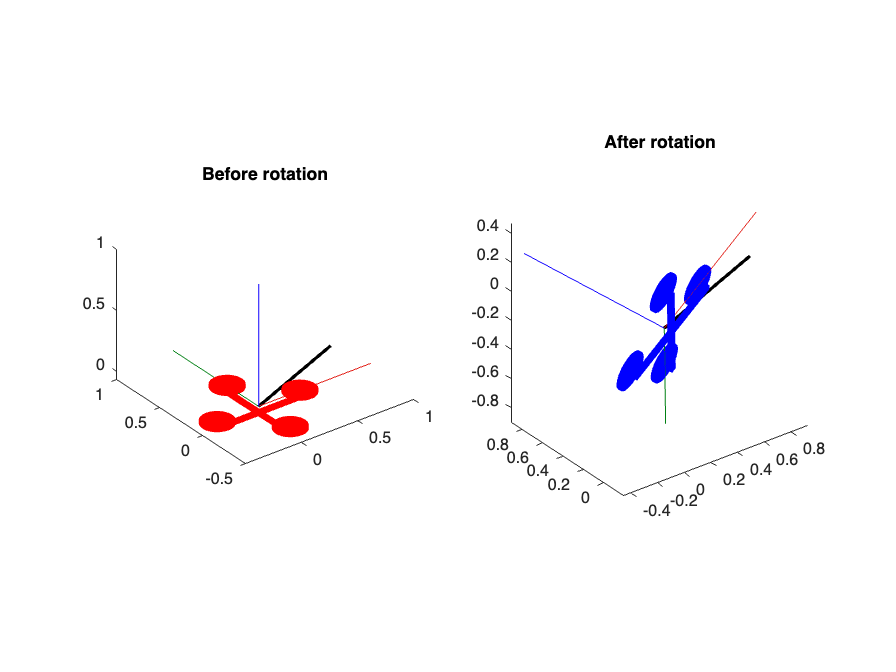

v_x = 1;    %x component of rotation vector
v_y = 0.4;    %y component of rotation vector
v_z = 0;    %z component of rotation vector
v = [v_x v_y v_z]'; 
v = v/norm(v);  %normalised rotation vector

alpha = -70*pi/180;    %rotation angle

S = [0   -v_z  v_y;    %skew-symmetric form of rotation vector
     v_z  0   -v_x;
    -v_y  v_x  0];

% R = expm(S*alpha);
R = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2;    %Rodrigues' formula to determine R

%plot figures
figure 
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'multirotor.stl',"MeshColor","red")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('Before rotation')

subplot(1,2,2)
plotTransforms([0 0 0],rotm2quat(R),"MeshFilePath",'multirotor.stl',"MeshColor","blue")
line([0 v(1)],[0,v(2)],[0,v(3)],'Color','black','LineStyle','-','LineWidth',2)
axis equal,title('After rotation') 

**  Question 2: **Use Rodrigues' formula to determine the rotation matrix that is described by exponential coordinates of $\alpha\hat{\bf v}=[0.2~~0.3~~0.5]^T$.

**Answer:**


$$\alpha\hat{\bf v}=[0.2~~0.3~~0.5]^T~~\rightarrow ~~\alpha = \sqrt{0.2^2+0.3^2+0.5^2}=0.6164,\qquad \hat{\bf v}=\frac{1}{\alpha}[0.2~~0.3~~0.5]^T=[0.324~0.487~~0.811]^T.$$
 


$$\begin{array}{ll}
{^W{\bf R}_B}
&=\mathrm{e}^{\lfloor ^W\hat{\bf v} \rfloor\alpha},\\
&=I+\sin\alpha\lfloor ^W\hat{\bf v} \rfloor +\left(1-\cos\alpha\right)\lfloor ^W\hat{\bf v} \rfloor^2,\\
&=I+\sin(0.616)\left[\begin{array}{cccccccc}    0 & -0.811 & 0.487\\
0.811 & 0 & -0.324\\
-0.487 & 0.324 & 0    \\ \end{array}\right]+\left(1-\cos(0.616)\right)\left[\begin{array}{cccccccc}    0 & -0.811 & 0.487\\
0.811 & 0 & -0.324\\
-0.487 & 0.324 & 0    \\ \end{array}\right]^2,\\
&= \left[\begin{array}{cccccccc}    0.835 & -0.44 & 0.33\\
0.498 & 0.86 & -0.115\\
-0.233 & 0.26 & 0.937    \\ \end{array}\right].
\end{array}$$


%Answer block (if required)
alphaV = [0.2 0.3 0.5]';
alpha = norm(alphaV)

alpha = 0.6164

v = alphaV/alpha

v =     0.3244
    0.4867
    0.8111



S = [0 -v(3) v(2);    %skew-symmetric form of rotation vector
     v(3) 0 -v(1);
     -v(2) v(1) 0];

R = expm(S*alpha)    %rotation matrix determined from matrix exponential

R =     0.8353   -0.4399    0.3298
    0.4980    0.8595   -0.1149
   -0.2329    0.2602    0.9370


R_ = eye(3)+sin(alpha)*S+( 1-cos(alpha) )*S^2    %rotation matrix determined using Rodrigues' formula

R_ =     0.8353   -0.4399    0.3298
    0.4980    0.8595   -0.1149
   -0.2329    0.2602    0.9370


vpa(R_,3)

$$ans = \left(\begin{array}{ccc} 0.835 & -0.44 & 0.33\\ 0.498 & 0.86 & -0.115\\ -0.233 & 0.26 & 0.937 \end{array}\right)$$

### Principal axis rotations

Recalling that our rotation matrix can be parameterised by the axis-angle representation as


$${\bf R}= \left[\begin{array}{cccccccc}    \mathrm{c}_\alpha+\hat{v}_x^2(1-\mathrm{c_\alpha}) & \hat{v}_x\hat{v}_y(1-\mathrm{c}_\alpha)-\hat{v}_z\mathrm{s}_\alpha & \hat{v}_x\hat{v}_z(1-\mathrm{c}_\alpha)+\hat{v}_y\mathrm{s}_\alpha \\    \hat{v}_x\hat{v}_y(1-\mathrm{c}_\alpha)+\hat{v}_z\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_y^2(1-\mathrm{c_\alpha}) & \hat{v}_y\hat{v}_z(1-\mathrm{c}_\alpha)-\hat{v}_x\mathrm{s}_\alpha  \\    \hat{v}_x\hat{v}_z(1-\mathrm{c}_\alpha)-\hat{v}_y\mathrm{s}_\alpha & \hat{v}_y\hat{v}_z(1-\mathrm{c}_\alpha)+\hat{v}_x\mathrm{s}_\alpha & \mathrm{c}_\alpha+\hat{v}_z^2(1-\mathrm{c_\alpha})    \\ \end{array}\right],$$


we can easily form the three principal axis rotations of:

- ${\bf R}_x={\bf R}(\alpha,\hat{\bf x})$ — rotation of $\alpha$ about $x$ axis,

- ${\bf R}_y={\bf R}(\alpha,\hat{\bf y})$ — rotation of $\alpha$ about $y$ axis,

- ${\bf R}_z={\bf R}(\alpha,\hat{\bf z})$ — rotation of $\alpha$ about $z$ axis,

by adjusting the components of $\hat{\bf v}=[v_x ~v_y~v_z]^T$ in the rotation matrix equation above.

Specifically, if we set $\hat{\bf v}=[1 ~0~0]^T$ in the rotation matrix equation above, we obtain


$$\begin{array}{cc}{\mathbf R}_x = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\alpha} & -\sin{\alpha \\    0 & \sin{\alpha} & \cos{\alpha}    \\ \end{array}\right],\\ \end{array}$$


if we set $\hat{\bf v}=[0 ~1~0]^T$ we obtain


$$\begin{array}{cc}{\mathbf R}_y = \left[\begin{array}{cccccccc}    \cos{\alpha} & 0 & \sin{\alpha} \\    0 & 1 & 0 \\    -\sin{\alpha} & 0 & \cos{\alpha}    \\ \end{array}\right],\\ \end{array}$$


and if we set $\hat{\bf v}=[0 ~0~1]^T$ we get


$$\begin{array}{cc}{\mathbf R}_z = \left[\begin{array}{cccccccc}    \cos{ \alpha} & -\sin{ \alpha} & 0 \\    \sin{ \alpha } & \cos{ \alpha } & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


These results match of the Euler angle formulation supplied in Chapter 3.

**  Question 3: **Determine the rotation matrix corresponding to a rotation about $\hat{\bf v}=[-1 ~0~0]^T$ with a rotation angle of $\alpha=\gamma$.

**Answer:**


$$\begin{array}{cc}{\mathbf R} = \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & \cos{\gamma} & \sin{\gamma \\    0 & -\sin{\gamma} & \cos{\gamma}    \\ \end{array}\right],\\ \end{array}$$


%Answer block (if required)


### Matrix logarithms of rotations

We can recover the exponential coordinates, $\alpha\hat{\bf v}$ from a rotation matrix ${\bf R}$ using a **matrix logarithm **operation, which is the *inverse* of the matrix exponential. Specifically, if the rotation matrix is given by


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf v} \rfloor\alpha},$$


then the matrix logarithm of the rotation matrix yields


$$\log{\bf R}= {\lfloor \hat{\bf v} \rfloor\alpha}.$$


Based on this, we can think of the matrix exponential as in *integration operator *for the exponential coordinates, and the matrix logarithm as a *differentiation operator*.

#### Example: Matrix logarithm

Using MATLAB, determine the rotation matrix corresponding to $\hat{\bf v}=[0~0.866~0.6]^T$ and $\alpha=30^\circ$, and show that the exponential coordinates can be recovered using the matrix logarithm.

v = [0 0.866 0.5]'    %rotation vector
alpha = 30*pi/180     %rotation angle


R =     0.7800   -0.4270    0.4570
    0.5730    0.7800   -0.2500
   -0.2500    0.4570    0.8540


S = [0 -v(3) v(2);    %skew-symmetric form of rotation vector
     v(3) 0 -v(1);
     -v(2) v(1) 0];

R = expm(S*alpha);    %rotation matrix from matrix exponential

alphaV_ =     0.3927
    0.3927
    0.5554


$$aV = \left(\begin{array}{c} 0.393\\ 0.393\\ 0.555 \end{array}\right)$$

S_ = logm(R);         %matrix logarithm of rotation matrix
va = [-S_(2,3) S_(1,3) -S_(1,2)]';    %recovered exponential coordinates
alpha_ = norm( va )   %recovered rotation angle
v_ = va/alpha         %recovered rotation vector

Instead of having to use the matrix logarithm, which is computationally heavy on embedded systems, an algorithm exists that can determine the exponential coordinates. The rotation angle can be determined from the rotation matrix using


$$\alpha=\cos^{-1}\left(\frac{\mathrm{tr}{\bf R}-1}{2}\right),$$


where $\mathrm{tr}{\bf R}$ corresponds to the trace of matrix ${\bf R}$, namely, summing the diagonal entries of ${\bf R}$:

$\mathrm{tr}{\bf R}=r_{11}+r_{22}+r_{33}$.

For $\alpha\neq \pi$, the rotation vector (in skew-symmetric form) is then determined by


$$\lfloor \hat{\bf v} \rfloor = \frac{1}{2\sin{\alpha}}\left({\bf R}-{\bf R}^T\right).$$


For the special case of $\alpha=\pi$, the rotation vector is one of the following solutions, which would need to be verified using ${\bf R}=\mathrm{e}^{\lfloor \hat{\bf v} \rfloor\alpha}=I+\sin\alpha\lfloor \hat{\bf v} \rfloor +\left(1-\cos\alpha\right)\lfloor \hat{\bf v} \rfloor^2$:


$$\hat{\bf v}=\frac{1}{\sqrt{2(1+r_{33})}}\left[\begin{array}{cc}    r_{13} \\   r_{23} \\    1+r_{33}    \\ \end{array}\right], \qquad \hat{\bf v}=\frac{1}{\sqrt{2(1+r_{22})}}\left[\begin{array}{cc}    r_{12} \\   1+r_{22} \\    r_{32}    \\ \end{array}\right]
, \qquad \hat{\bf v}=\frac{1}{\sqrt{2(1+r_{11})}}\left[\begin{array}{cc}    1+r_{11} \\   r_{21} \\    r_{31}    \\ \end{array}\right].$$


**  Question 4: **Determine the exponential coordinates using the formulae above when ${\bf R} = \left[\begin{array}{ccc}
0.78 & -0.427 & 0.457\\
0.573 & 0.78 & -0.25\\
-0.25 & 0.457 & 0.854
\end{array}\right]$.

**Answer:**

$\alpha\hat{\bf v}=\left[\begin{array}{c}
0.393\\
0.393\\
0.555
\end{array}\right]$.

%Answer block (if required)

R_ =     0.7803   -0.4268    0.4571
    0.5732    0.7803   -0.2500
   -0.2500    0.4571    0.8536


R = [0.78 -0.427 0.457;
     0.573 0.78 -0.25;
    -0.25  0.457  0.854]

alpha_ = acos( (trace(R)-1)/2 );
S_ = 1/(2*sin(alpha_))*(R-R');
v_ = [S_(3,2) S_(1,3) S_(2,1)]';
alphaV_ = alpha_*v_
aV = vpa(alphaV_,3)

S = [0 -alphaV_(3) alphaV_(2);
     alphaV_(3) 0 -alphaV_(1);
     -alphaV_(2) alphaV_(1) 0];
R_ = expm(S)

### The dot product and cross product

Recall that the cross product of two unitary vectors is described by


$$\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf c},$$


where $\theta$ describes the angle between vectors $\hat{\bf a}$ and $\hat{\bf b}$, and $\hat{\bf c}$ defines the vector perpendicular to $\hat{\bf a}$ and $\hat{\bf b}$. Based on this description, if we were to rotate vector $\hat{\bf a}$ about vector $\hat{\bf c}$ with a rotation of $\theta$ units, we would obtain $\hat{\bf b}$, namely


$$\begin{array}{ll}
\hat{\bf b}
&={\bf R}\hat{\bf a},\\
&={\bf e}^{\lfloor\theta\hat{\bf c}\rfloor}\hat{\bf a}.\\
\end{array}$$


As such, $\theta\hat{\bf c}$ can be thought of as exponential coordinates describing the mapping from $\hat{\bf a}$ and $\hat{\bf b}$. This relationship is useful when deadling with multivariable control design (e.g. thrust vectoring control) and state estimation (comparing vector directions) — both of which will be explored later in this course. Note that when $\theta$ is sufficiently small, the exponential coordinates can be suitably approximated by $\hat{\bf a}\times \hat{\bf b}=\sin{\theta} \hat{\bf n}\approx {\theta} \hat{\bf n}$.

Recall the dot product of two unitary vectors:


$${\hat{\bf a}}\cdot {\hat{\bf b}}=\cos\theta.$$


Given known $\hat{\bf a}$ and $\hat{\bf b}$, the rotation angle can be recovered by


$$\begin{array}{ll}
\theta 
&= \cos^{-1}\left({\hat{\bf a}}\cdot {\hat{\bf b}}\right), 
\end{array}$$


where $\theta \in [0,\pi]$. The rotation vector is then determined by


$${\hat{\bf c}}=\frac{1}{\sin\theta}\hat{\bf a}\times \hat{\bf b}.

$$


Note that the inverse cosine function will return a value of $\theta$ between $0$-$\pi$. Additionally, if $\hat{\bf a}$ and $\hat{\bf b}$ are anti-parallel, determination of $\hat{\bf c}$ using the equation above will be incorrect, as  $\hat{\bf a}\times \hat{\bf b}={\bf 0}$ and $\theta=\pi$. Specifically, when vectors $\hat{\bf a}$ and $\hat{\bf b}$ are collinear (form a line), any rotation vector and rotation angle $\theta=\pi$ will map $\hat{\bf a}$ to $\hat{\bf b}$. In this case, one could arbitrarily choose a vector lies in the plane orthogonal to this line.

#### Example: Cross product and rotation matrix

a = [1 2 3]';        %arbitrary vector a
a = a/norm(a);        %arbitrary normalised vector a
b = [-1 1 3]';        %arbitrary vector b
b = b/norm(b)        %arbitrary normalised vector b

b =    -0.3015
    0.3015
    0.9045



n = cross(a,b);    %cross product of vectors a and b
theta = acos( dot(a,b));    %rotation angle between a and b
c = n/sin(theta);    %rotation vector perpendicular to a and b

phi = theta*c;    %exponential coordinates
S = [0 -phi(3) phi(2);    %skew-symmetric form of exponential coordinates
    phi(3) 0 -phi(1);
    -phi(2) phi(1) 0];

R = expm(S);    %rotation matrix
b_ = R*a        %determining vector b using rotation matrix 

b_ =    -0.3015
    0.3015
    0.9045


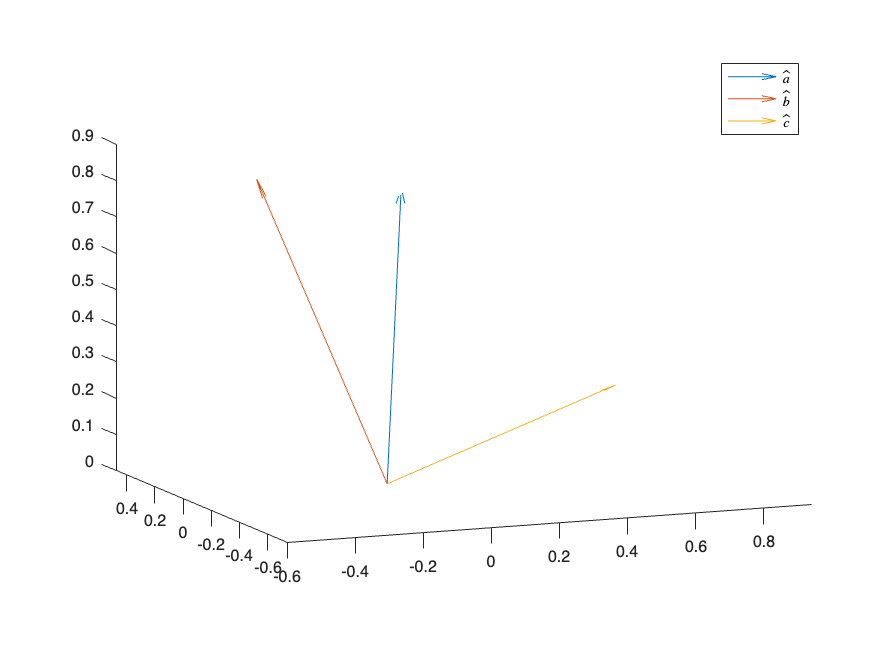


%plot figures
figure, hold on
quiver3(0,0,0,a(1),a(2),a(3))
quiver3(0,0,0,b(1),b(2),b(3))
quiver3(0,0,0,c(1),c(2),c(3))
legend('$\hat{a}$','$\hat{b}$','$\hat{c}$','Interpreter','Latex')
axis equal

%set x-y axis limits and view angle
xlim([-0.60 0.94])
ylim([-0.74 0.47])
view([-22.493 9.992])

**  Question 5: **Using the cross product and dot product, determine the rotation matrix that maps $\hat{\bf a}=[\frac{1}{\sqrt{2}}~0~\frac{1}{\sqrt{2}}]^T$ to $\hat{\bf b}=[0~1~0]^T$.

**Answer:**


$${\bf R}=\left[\begin{array}{ccc}
0.5 & -0.707 & -0.5\\
0.707 & 0 & 0.707\\
-0.5 & -0.707 & 0.5
\end{array}\right].$$


%Answer block (if required)
a = [1/sqrt(2) 0 1/sqrt(2)]';        %arbitrary vector a
b = [0 1 0]';        %arbitrary vector b

n = cross(a,b);    %cross product of vectors a and b
theta = acos( dot(a,b));    %rotation angle between a and b
c = n/sin(theta);    %rotation vector perpendicular to a and b

phi = theta*c;    %exponential coordinates
S = [0 -phi(3) phi(2);    %skew-symmetric form of exponential coordinates
    phi(3) 0 -phi(1);
    -phi(2) phi(1) 0];

R = expm(S);    %rotation matrix
b_ = R*a        %determining vector b using rotation matrix 

b_ =          0
    1.0000
    0.0000


R = vpa(R,3)

$$R = \left(\begin{array}{ccc} 0.5 & -0.707 & -0.5\\ 0.707 & 0 & 0.707\\ -0.5 & -0.707 & 0.5 \end{array}\right)$$

## Angular velocity

Angular velocity will dictate how our orientation changes over time, so we are therefore interested in how the two are related when dealing with multiple reference frames. This is important when mathematically modelling systems (for example when designing simulation environments) and also when angular rate information is available from a sensor (for example a gyroscope) and we want to estimate orientation from it. 

In the case of planar rotations (resulting in rotations about a fixed principle axis) the relationship is trivial, but we require more scrutiny for the generalised spatial case when up to three degrees of rotation freedom are at work.

### Rotation matrix derivative

To understand the relationship between angular velocity and orientation, we need to develop a better understanding of reference frame motion as they rotate. Consider the motion of a point fixed to the end of ${^W\hat{\bf x}_B$ when $\{B\}$ experiences and angular velocity of ${^W{\bf \omega}}$, as shown in the figure below.

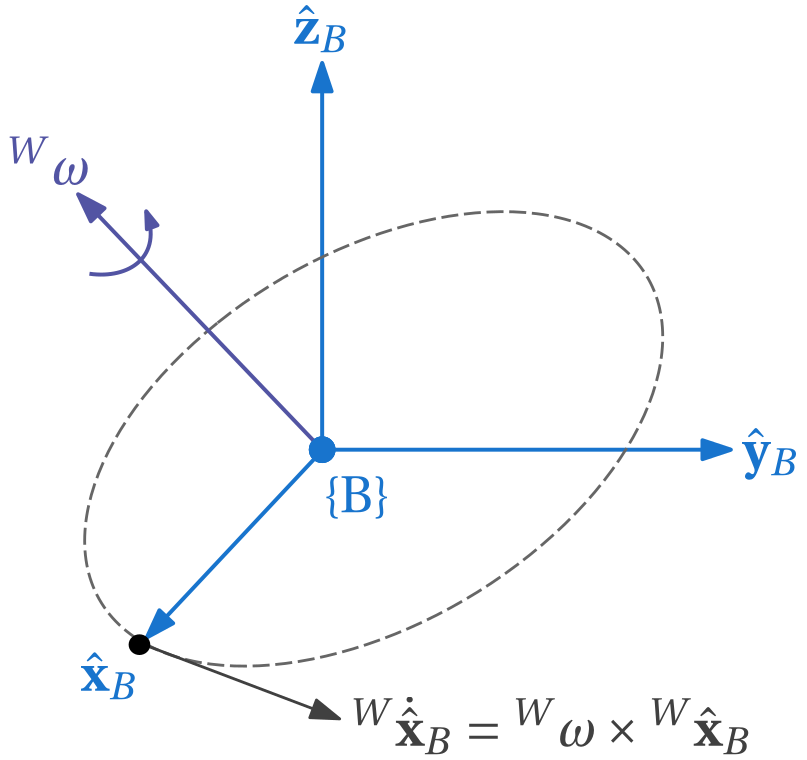

Recall that ${^W\hat{\bf x}_B$ describes the $x$-axis of the body frame when described in the world frame, which is obtained by


$$\begin{array}{ll}
{^W\hat{\bf x}_B
&={^W{\bf R}_B\hat{\bf x}_B,\\
&={^W{\bf R}_B\left[\begin{array}{cccccccc}    1 \\    0 \\   0    \\ \end{array}\right].\\
\end{array}$$


Given the orthogonality property of ${^W{\bf R}_B$, ${^W\hat{\bf x}_B$ will always have unit length. This means that during rotation, only the direction of ${^W\hat{\bf x}_B$ will change — not the length. Given that the angular velocity of the body frame is described in the world frame as ${^W{\bf \omega}}$, we can determine the rate of change of ${^W\hat{\bf x}_B$ based on elementary mechanics, namely

${^W\dot{\hat{\bf x}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf x}}_B}$.

We can repeat this process for the other two axes of $\{B\}$without loss of generality, which yields 

${^W\dot{\hat{\bf y}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf y}}_B}$.

${^W\dot{\hat{\bf z}}_B}={^W{\bf\omega}}\times {^W{\hat{\bf z}}_B}$.

Recalling that


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right],\ \end{array}$$


the derivative of the rotation matrix follows as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    ^W\dot{\hat{\mathbf x}}_B & ^W\dot{\hat{\mathbf y}}_B & ^W\dot{\hat{\mathbf z}}_B    
\end{array}\right],\\
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right].\\


\end{array}$$


Making use of our skew-symmetric form for the cross product, namely


$$\begin{array}{cc}
{{\bf \omega} \times {\bf r} = 
\lfloor {\mathbf\omega} \rfloor {\bf r}, \end{array}$$


we can express the rotation matrix derivative as


$$\begin{array}{ll}^W\dot{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    {^W{\bf\omega}}\times {^W\hat{\bf x}_B} & {^W\bf\omega}\times {^W\hat{\bf y}_B} & {^W{\bf\omega}}\times {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor \left[\begin{array}{cccc}     {^W\hat{\bf x}_B} &  {^W\hat{\bf y}_B} &  {^W\hat{\bf z}_B}\\
\end{array}\right],\\
& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}.

\end{array}$$


This result is quite interesting, as it suggests that the rate of change of our orientation encoder will be a function of both the angular velocity vector and current orientation. It can be shown that for any ${\bf R}\in$ SO(3) and $\bf \omega\in \mathbb{R}^3$,


$$\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T. \end{array}$$


Recalling that we can relate the angular velocity between different frames using


$$\begin{array}{cc}{^W\mathbf\omega} = {^W{\mathbf R}_B} {^B\mathbf\omega}, \end{array}$$


and this, along with the result above of $\begin{array}{cc}\lfloor {\mathbf R}{\mathbf\omega} \rfloor = {\mathbf R}\lfloor {\mathbf\omega} \rfloor {\mathbf R}^T \end{array}$ can be used to determine the rotation matrix derivative as a function of ${^B\mathbf\omega}$:


$$\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = \lfloor {{^W{\mathbf R}_B}^B\mathbf\omega} \rfloor  {^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  {^W{\mathbf R}^T_B}{^W{\mathbf R}_B},\\
& = {^W{\mathbf R}_B}\lfloor {^B\mathbf\omega} \rfloor  .
\end{array}$$


Note the similarity when determining $\begin{array}{ll}^W\dot{\mathbf R}_B 



\end{array}$ as a function of $^W{\bf \omega}$ and $^B{\bf \omega}$. 

**  Question 6: **Determine the rotation matrix derivative corresponding to when frame $\{B\}$, currently coincident with frame $\{W\}$, experiences an angular velocity in the body frame of ${\bf\omega}=[0~~0.2~~0.2]^T$.

**Answer:**


$${^W\dot{\bf R}_B}=\left[\begin{array}{ccc}
0 & -0.2 & 0.2\\
0.2 & 0 & 0\\
-0.2 & 0 & 0
\end{array}\right].$$$


%Answer block (if required)
R = eye(3);
w = [0 0.2 0.2]';
S = [ 0   -w(3) w(2);
      w(3) 0   -w(1);
     -w(2) w(1) 0];
R_dot = R*S

R_dot =          0   -0.2000    0.2000
    0.2000         0         0
   -0.2000         0         0


$$R\_dot = \left(\begin{array}{ccc} 0 & -0.2 & 0.2\\ 0.2 & 0 & 0\\ -0.2 & 0 & 0 \end{array}\right)$$

### Quaternion derivative

The relationship between angular velocity and the quaternion follows a similar pattern to that of the rotation matrix counterpart. The full derivation will be spared here for sake of time. Analogous to the result of $\begin{array}{ll}^W\dot{\mathbf R}_B 

& = \lfloor {^W\mathbf\omega} \rfloor  {^W{\mathbf R}_B}

\end{array}$, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W\mathbf\Omega}\otimes{^W{\mathbf q}_B},\end{array}$$


where 


$$\begin{array}{ll}
{^W\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^W{\bf\omega}    \\ \end{array}\right]\\
\end{array}$$


is a "pure" quaternion formed from the angular velocity vector in frame $\{W\}$. Using appropriate identities, the quaternion derivative can be written as 


$$\begin{array}{cc}{^W\dot{\mathbf q}_B} = \frac{1}{2}{^W{\mathbf q}_B}\otimes{^B\mathbf\Omega},\end{array}$$


where


$$\begin{array}{ll}
{^B\mathbf\Omega}
&=\left[\begin{array}{cccccccc}    0 \\    ^B{\bf\omega}    \\ \end{array}\right],
\end{array}$$


which follows a similar structure but now using the angular velocity in $\{B\}$. 

## Obtaining orientation from angular velocity

If the angular velocity is known exactly, we can use this information to determine the corresponding orientation at a given time using integration. We must, however, take into account the particular reference frame mapping, such as from $\{B\}$ to $\{W\}$ when the velocity is described in $\{B\}$, before performing the integration operation — otherwise the resulting "orientation" described in $\{B\}$ is meaningless in general.

### Rotation matrix formulation

The incremental orientation can be determined in rotation matrix form using exponential coordinates. Recall that 


$${\bf R}=\mathrm{\bf e}^{\lfloor \alpha\hat{\bf v} \rfloor}=\mathrm{\bf e}^{\lfloor \hat{\bf v} \rfloor\alpha},$$


where $\alpha\hat{\bf v}$ are the exponential coordinates describing a generalised 3D rotation. Assuming a body experiences an angular velocity vector of ${^B{\bf \omega}}$, expressed in $\{B\}$, for a duration of $\Delta t$ units of time, we can determine the incremental exponential coordinates corresponding to rotating about vector ${^B{\bf \omega}}$ for $\Delta t$ units of time (usually seconds) using 


$${^B{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental rotation angle and normalised rotation vector follow respectively as 


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$



$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|}.$$


The corresponding incremental rotation matrix is given by


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{\bf e}^{\lfloor {^B{\bf \theta}} \rfloor},\\
&=\mathrm{\bf e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


If our orientation is originally described as $^W{\bf R}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf R}_{\{1\}}}$, by post-multiplying $^W{\bf R}_{\{0\}}$ by the incremental rotation matrix, namely


$${^W{\bf R}_{\{1\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}},$$
 

where $\Delta{\bf R}={^{\{0\}}{\bf R}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is generalised as


$${^W{\bf R}_{\{n\}}}={^W{\bf R}_{\{0\}}}{^{\{0\}}{\bf R}_{\{1\}} \dots {^{\{n-1\}}{\bf R}_{\{n\}}.$$
 

Note that we are post-multiplying in each instance, as the rotation vector is described in $\{B\}$. If instead we had information of ${^W{\bf \omega}}$, we would need to pre-multiply in each instance.

**  Question 7: **Given an initial orientation of ${^W{\bf R}_{\{0\}}}=\left[\begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right]$, if the robot then experiences an angular velocity in the current frame of $^0{\bf\omega}=[0~~0.2~~0.2]^T$ for a duration of $\Delta t=1$ seconds, determine the new orientation with respect to $\{W\}$.

**Answer:**


$${^W{\bf R}_{\{1\}}}=\left[\begin{array}{ccc}
-0.197 & -0.98 & -0.0199\\
0.96 & -0.197 & 0.197\\
-0.197 & 0.0199 & 0.98
\end{array}\right].$$


%Answer block (if required)
R0 = [0 -1 0; 1 0 0; 0 0 1];
dt = 1;
the = dt*[0 0.2 0.2]';
S = [ 0   -the(3) the(2);
      the(3) 0   -the(1);
     -the(2) the(1) 0];
R1 = R0*expm(S)

R1 =    -0.1973   -0.9801   -0.0199
    0.9603   -0.1973    0.1973
   -0.1973    0.0199    0.9801


vpa(R1,3)

$$ans = \left(\begin{array}{ccc} -0.197 & -0.98 & -0.0199\\ 0.96 & -0.197 & 0.197\\ -0.197 & 0.0199 & 0.98 \end{array}\right)$$

**  Question 8: **Given an initial orientation of ${^W{\bf R}_{\{0\}}}=\left[\begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right]$, determine the frame $\{0\}$ angular velocity that would be experienced in order to obtain ${^W{\bf R}_{\{1\}}}=
 \left[\begin{array}{cccccccc}    0.835 & -0.44 & 0.33\\
0.498 & 0.86 & -0.115\\
-0.233 & 0.26 & 0.937    \\ \end{array}\right]$ over a time period of $\Delta t=0.5$ seconds. You can assume that the angular velocity is constant throughout the motion.

**Answer:**


$$^0{\bf\omega}=\left[\begin{array}{c}
0.734\\
0.147\\
-2.11
\end{array}\right].$$


%Answer block (if required)
R0 = [0 -1 0; 1 0 0; 0 0 1];
R1 = [0.835 -0.44 0.33;
      0.498 0.86 -0.115;
     -0.233 0.26 0.937];
dT = 0.5;
dR = R0'*R1;
alpha_ = acos( (trace(dR)-1)/2 );
S_ = 1/(2*sin(alpha_))*(dR-dR');
v_ = [S_(3,2) S_(1,3) S_(2,1)]';
w_ = alpha_*v_/dT

w_ =     0.7335
    0.1467
   -2.1074



the = dT*w_;
S = [ 0   -the(3) the(2);
      the(3) 0   -the(1);
     -the(2) the(1) 0];
R1 = R0*expm(S)

R1 =     0.8354   -0.4398    0.3298
    0.4979    0.8596   -0.1149
   -0.2329    0.2602    0.9370


vpa(w_,3)

$$ans = \left(\begin{array}{c} 0.734\\ 0.147\\ -2.11 \end{array}\right)$$

### Quaternion formulation

Recall that the quaternion encodes the exponential coordinates. Given our previously defined incremental axis-angle representation of


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
        
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


we can determine the corresponding incremental quaternion as


$$\begin{array}{cc}\Delta{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha}{2}} \\ \sin{\frac{\Delta\alpha}{2}} {^B\hat{\mathbf \omega}}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \\     \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_x \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_y \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_z    \\ \end{array}\right].\end{array}$$


If our orientation is originally described by $^W{\bf q}_{\{0\}}$ prior to experiencing the angular velocity, we can then determine our updated orientation, ${^W{\bf q}_{\{1\}}}$, by post-multiplying $^W{\bf q}_{\{0\}}$ by the incremental quaternion, namely


$${^W{\bf q}_{\{1\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}},$$
 

where $\Delta{\bf q}={^{\{0\}}{\bf q}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. This process can be repeated any number of times, assuming one is able to capture each incremental rotation matrix that corresponds to the angular velocity that was experienced for the given time frame. This is expressed as


$${^W{\bf q}_{\{n\}}}={^W{\bf q}_{\{0\}}}\otimes{^{\{0\}}{\bf q}_{\{1\}}\otimes \dots \otimes{^{\{n-1\}}{\bf q}_{\{n\}}.$$
 

As with the rotation matrix formulation, we are post-multiplying in each instance, as the rotation vector is described in $\{B\}$. If instead we had information of ${^W{\bf \omega}}$, we would need to pre-multiply in each instance.

#### Example: Determining quaternion-based orientation from angular velocity

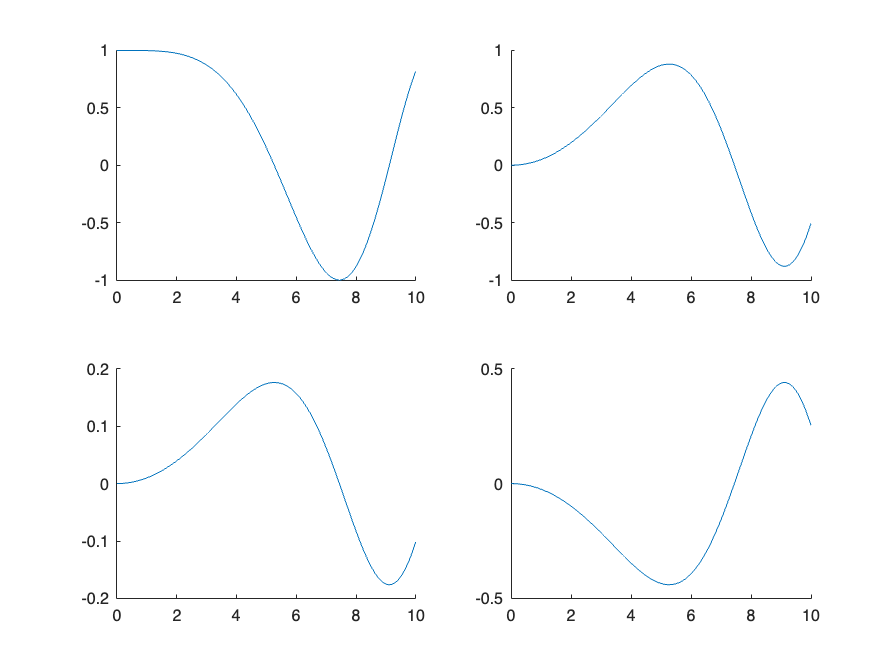

dT = 0.01;  %sampling duration
numSamples = 1000;      %number of samples
t = (0:numSamples-1)*dT;    %time vector

omega1 = linspace(0,1,numSamples);
omega2 = linspace(0,0.2,numSamples);
omega3 = linspace(0,-0.5,numSamples);
omega = [omega1' omega2' omega3'];  %generate arbitrary 3D angular velocity


q = zeros(numSamples,4);    %initialise quaternion array
q(1,1:4) = [1 0 0 0];       %initialise first sample of quaternion to be null quaternion

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT; %determine incremental exponential coordinates
    dalpha = norm(dtheta);  %determine incremental rotation angle
    if( dalpha == 0)        %determine incremental rotation vector
        v = [0 0 0];
    else
        v = dtheta/dalpha;
    end
    dq = [cos(dalpha) sin(dalpha)*v];   %populate incremental quaternion
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq); %calculate updated quaternion at sample instance k+1
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) ); %normalise quaternion
end
%plot figure
figure
subplot(2,2,1),hold on
plot(t,q(:,1))
subplot(2,2,2),hold on
plot(t,q(:,2))
subplot(2,2,3),hold on
plot(t,q(:,3))
subplot(2,2,4),hold on
plot(t,q(:,4))

**  Question 9: **Given an initial orientation of ${^W{\bf q}_{\{0\}}}=\left[\begin{array}{ccc}
0 & -1 & 0 & 0\\
\end{array}\right]^T$, and an angular velocity vector of $^0{\bf\omega}=\left[\begin{array}{c}
0 &
-\pi &
0
\end{array}\right]^T$ experienced over $\Delta t=2$ seconds, determine the updated quaternion orientation, ${^W{\bf q}_{\{1\}}}$.

**Answer:**


$${^W{\bf q}_{\{1\}}}=\left[\begin{array}{ccc}
0 & 1 & 0 & 0\\
\end{array}\right]^T=\left[\begin{array}{ccc}
0 & -1 & 0 & 0\\
\end{array}\right]^T$$


%Answer block (if required)
q0 = [0 -1 0 0]';
w0 = [0 -pi 0]';
dT = 2;
alpha = dT*norm(w0);
v = w0/norm(w0);

dq = [cos(alpha/2) sin(alpha/2)*v'];
q1 = quatmultiply(q0',dq)

q1 =          0    1.0000         0    0.0000


**  Question 10: **Select two benefits of using quaternions over rotation matrices when calculating orientation from angular velocity.

**Answer:**

- Less number of computations required (addition and multiplication) when doing quaternion multiplication over matrix multiplication.

- Storing four numbers for quaternions instead of nine numbers for a rotation matrix.

**  Question 11: **Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.